# Adaptive Model Predictive Control for Leukemia Treatment

## 1.1 Initialization

clear all;
clc; 
close all; 

% Initialization (from Jost et al. - population average)
bsa = 1.71; % should be from patient data
params = (0.146); % true value of theta(7)
params_guess = (0.5);
theta = [31.2;12.72;0.019;9.9216;0.219*(bsa^1.16);2.06;params(1);0.103;0.866;2.3765];

% initial values (from Jost et al.)
x0 = [0;...
    0;...
    0;...
    theta(6)*theta(10)/theta(7);...
    theta(6)*theta(10)/theta(7);...
    theta(6)*theta(10)/theta(7);...
    theta(6)*theta(10)/theta(7);...
    theta(6)];

N = 34; % number of cycles
N_cycledays = 21; % for Steve we use 21 days
N_drugdays = 14; % for Steve we use 14 days

% Dimension
n = 8; % dimension of state vector x 
m = 1; % dimension of observation vector y

step_size = 0.05;
num_tpts = N_cycledays/step_size + 1;
tspan = linspace(0, N_cycledays, num_tpts);

t_oncycle = N_drugdays/step_size;
t_offcycle = (N_cycledays-N_drugdays)/step_size;
t_fullcycle = t_oncycle + t_offcycle + 1;

u_k = 50*bsa;
x0_k = x0;
t_start = 0;
lower = 1; upper = 2;


## 1.2 Calculate Nominal Trajectory

x_nominal = zeros([N*num_tpts n]);
t_nominal = zeros([N*num_tpts 1]);
u_nominal = zeros([N*t_fullcycle 1]);

for k=1:N
    [t_k,x_k] = ode45(@(t,x)jost(t,x,u_k,params,N_cycledays,N_drugdays),tspan,x0_k);
    
    i = t_fullcycle*(k-1);
    u_nominal(i+1:i+t_oncycle,:) = u_k*(ones(t_oncycle,1));
    
    if x_k(end,8) < lower
        u_k = 0.8*u_k;
    elseif x_k(end,8) > upper
        u_k = 1.2*u_k;
    end
    
    i = num_tpts*(k-1);
    x_nominal(i+1:i+num_tpts,:) = x_k;
    t_nominal(i+1:i+num_tpts,:) = t_k + 21*(k-1);
    x0_k = x_k(end,:);
end
rho = x_nominal(:,8);
clear k t_k x_k u_k i x0_k tspan


## 1.3 Plotting Nominal Trajectory

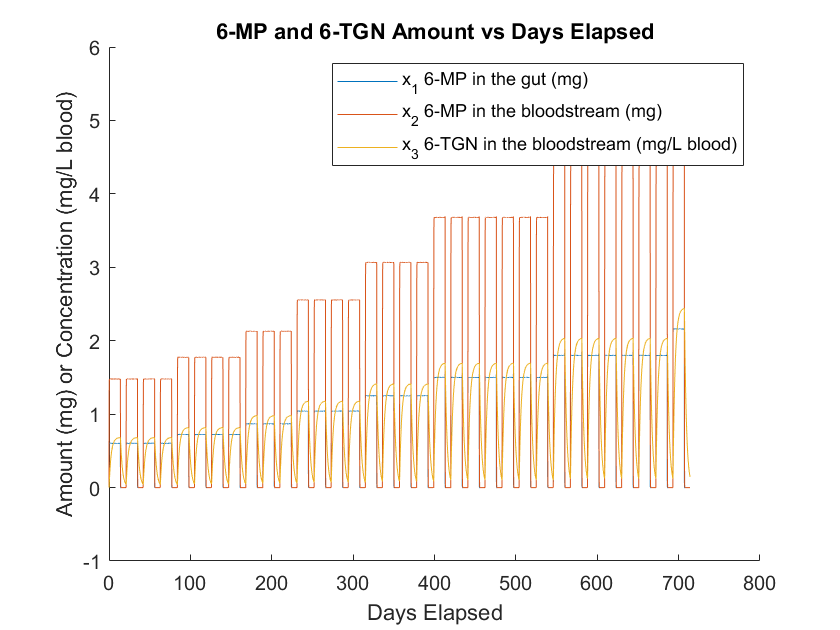

figure()
hold on
xlabel('Days Elapsed')
ylabel('Amount (mg) or Concentration (mg/L blood)')
title("6-MP and 6-TGN Amount vs Days Elapsed")
plot(t_nominal,x_nominal(:,1))
plot(t_nominal,x_nominal(:,2))
plot(t_nominal,x_nominal(:,3))
legend(...
    "x_1 6-MP in the gut (mg)", ...
    "x_2 6-MP in the bloodstream (mg)", ...
    "x_3 6-TGN in the bloodstream (mg/L blood)" ...
)
hold off

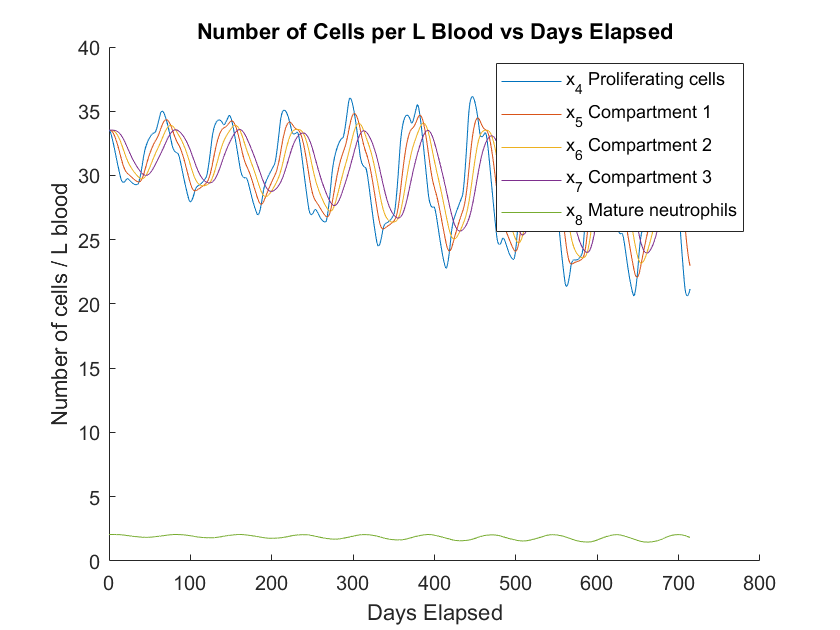


figure()
hold on
xlabel('Days Elapsed')
ylabel('Number of cells / L blood')
title("Number of Cells per L Blood vs Days Elapsed")
plot(t_nominal,x_nominal(:,4))
plot(t_nominal,x_nominal(:,5))
plot(t_nominal,x_nominal(:,6))
plot(t_nominal,x_nominal(:,7))
plot(t_nominal,x_nominal(:,8))
legend(...
    "x_4 Proliferating cells", ...
    "x_5 Compartment 1", ...
    "x_6 Compartment 2", ...
    "x_7 Compartment 3", ...
    "x_8 Mature neutrophils" ...
)
hold off

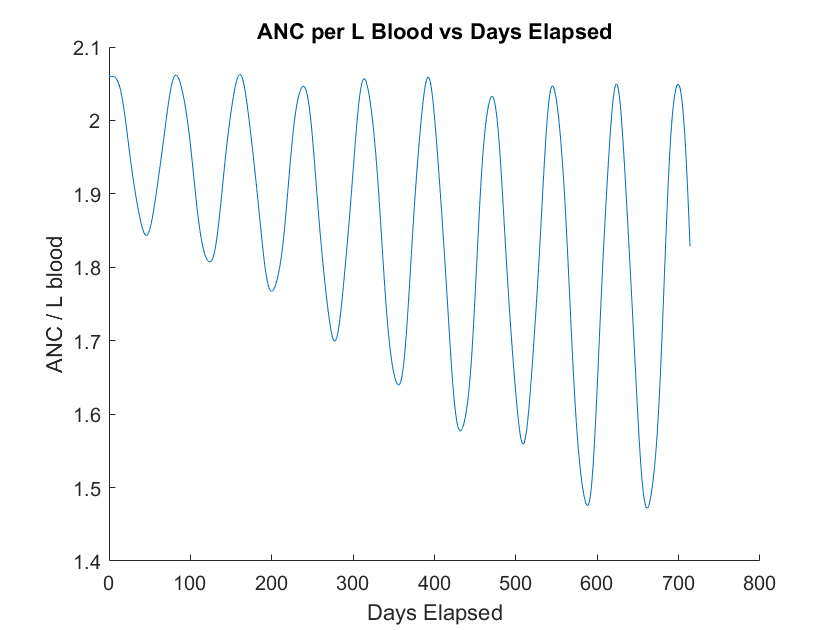


figure()
hold on
xlabel('Days Elapsed')
ylabel('ANC / L blood')
title("ANC per L Blood vs Days Elapsed")
plot(t_nominal,rho)
hold off

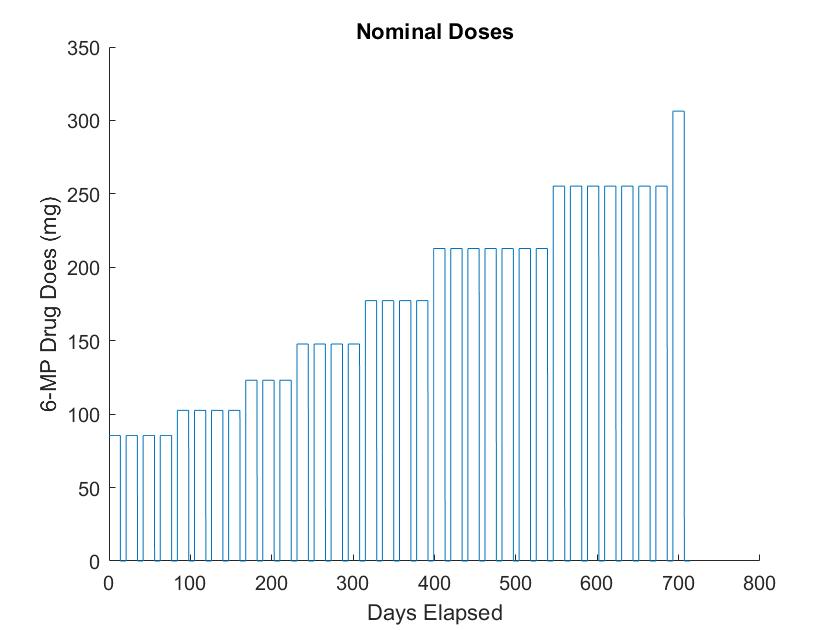


figure()
hold on
xlabel('Days Elapsed')
ylabel('6-MP Drug Does (mg)')
title("Nominal Doses")
plot(t_nominal,u_nominal)
hold off

## 1.4 Adaptive Model Predictive Controller

% Simulation Length
N_cycles=10;
N_cyclepred=5;

t_s = step_size;
t_end = N_cycledays*N_cycles;
N_steps = t_end / t_s;
N_steps_per_cycle = N_steps/N_cycles

N_steps_per_cycle = 420

N_steps_on_cycle = N_steps_per_cycle * (N_drugdays/N_cycledays)

N_steps_on_cycle = 280

time = (0:t_s:t_end);

% Nominal trajectory with new time vector
x_nominal = zeros([N_steps+1 n]);
u_nominal = zeros([N_steps+1 1]);
rho = zeros([N_steps+1 m]);

u_k=50*bsa;
x_nominal(1,:) = x0;
rho(1,:) = g_nonlin(x0);

for k=1:N_cycles
    for i=1:N_steps_per_cycle
        j = (N_steps_per_cycle*(k-1) + i);
        x_nominal(j+1,:) = jost_discrete(...
            j*t_s,x_nominal(j,:)',u_k,params,N_cycledays,N_drugdays,t_s ...
        );
        rho(j+1, :) = g_nonlin(x_nominal(j+1,:));
    end
    x_k = x_nominal(j+1,:);
    i = N_steps_per_cycle*(k-1);
    u_nominal(i+1:i+N_steps_on_cycle,:) = u_k*(ones(N_steps_on_cycle,1));
    
    if x_k(8) < lower
        u_k = 0.8*u_k;
    elseif x_k(8) > upper
        u_k = 1.2*u_k;
    end
end
% rho = x_nominal(:,8);

figure()
hold on
xlabel('Days Elapsed')
ylabel('ANC / L blood')
title("ANC per L Blood vs Days Elapsed")
plot(time,rho)
hold off

figure()
hold on
xlabel('Days Elapsed')
ylabel('6-MP Drug Does (mg)')
title("Nominal Doses")
plot(time,u_nominal)
hold off

% Generate disturbance and measurement noise given covariances Q,R
sigQ = 0.01;
sigR = 0.774341747;
Q_const = sigQ * eye(n);
R_const = sigR * eye(m);

d = zeros([n 1 N]);                 % disturbance
mn = zeros([m 1 N]);                % measurement noise

for i = 1:N_steps
    d(:,:,i) = Q_const * randn([n,1]);
    mn(:,:,i) = R_const * randn([m,1]);
end
clear sigQ sigR Q_const R_const i

% Simulate System
n_params = length(params);
x_calc = zeros([n,1,N_steps+1]);
y_calc = zeros([m,1,N_steps+1]);
params_calc = zeros([n_params,1,N_cycles+1]);
u_calc = zeros([1,N_cycles]);

x_calc(:,:,1) = x0;
y_calc(:,:,1) = g_nonlin(x0);
params_calc(:,:,1) = params_guess;

% u_calc(:,1) = 50*bsa;
% for k=1:N_steps_per_cycle
%     x_calc(:,:,k+1) = jost_discrete(k*t_s,x_calc(:,:,k), u_calc(1),params,N_cycledays,N_drugdays,t_s);
%     y_calc(:,:,k+1) = g_nonlin(x_calc(:,:,k+1));
% end

for k=1:N_cycles
    % this is the "previous day" to the cycle (number of days up to this point in the experiment)
    prev_i = N_cycledays*(k-1);
    if k == 1
        prev_i = 1;
    end
    
    disp(prev_i)
    
    % find vector p_star that minimizes measurement error
    % use nonlinear function f and g here
    f = @(p)calc_p_star_jost(p, params, x0, u_calc, prev_i, N_cycledays, N_drugdays, t_s);
    [p_star, fval] = fmincon(f,params_calc(:,:,k));
    
    % find input u that minimizes output error using best parameter guess
    % (the input u does not have access to p_actual)
    % find u by projecting the model with p_star into future
    % if all else fails we can try looking into the past as well as the future
    % x_calc(:,:,prev_i) is the last calculated value of x from the model
    % using p_actual
%     disp(prev_i/t_s);
    g = @(u)calc_adaptive_control_jost(...
        p_star, rho, x_calc(:,:,prev_i), u, u_calc, 10, 2.5, N_cyclepred, N_cyclepred, k, N_cycledays, N_drugdays, t_s, u_nominal(prev_i/t_s + 1) ...
    );
    % repmat(0.0001, [N_cyclepred 1]) adds a lower bound on u
    % repmat(u_calc(k), [N_cyclepred 1]) is the initial guess 
    % --> try initializing with nominal or with previous u
%     if k > 1
%         if y_calc(:,:,prev_i/t_s+1) < lower
%             init_guess_u = 0.8*u_calc(k-1);
%         elseif y_calc(:,:,prev_i/t_s+1) > upper
%             init_guess_u = 1.2*u_calc(k-1);
%         else
%             init_guess_u = u_calc(k-1);
%         end
%     else
%         init_guess_u = 50*bsa;
%     end
    init_guess_u = u_nominal(prev_i/t_s + 1);
    [u_star, gval] = fmincon(g,repmat(init_guess_u, [N_cyclepred 1]),[],[],[],[],repmat(0.01, [N_cyclepred 1]));
    disp("total cost");
    disp(gval);
    disp("inputs");
    disp(u_star);
    
    u_calc(k) = u_star(1);
    
    % u_calc(k+1) = u_star(2);
    params_calc(:,:,k+1) = p_star;
    
    % this is suppose to be the true system that the controller doesn't
    % know - controller is trying to learn the underlying true system
    if k == 1
        start_cycle = 1;
    else
        start_cycle = prev_i/t_s;
    end
    
%     if k > 1
%         if y_calc(:,:,prev_i/t_s) < lower
%             u_calc(k) = 0.8*u_calc(k-1);
%         elseif y_calc(:,:,prev_i/t_s) > upper
%             u_calc(k) = 1.2*u_calc(k-1);
%         else
%             u_calc(k) = u_calc(k-1);
%         end
%     else
%         u_calc(k) = 50*bsa;
%     end

    % calculating the states using the calculated control input and
    % p_actual (which the controller doesn't know - the true system)
    for l=start_cycle:start_cycle + (N_steps_per_cycle-1)
        % l is step number and t_s is timestep so l*t_s gives the time in days
        x_calc(:,:,l+1) = jost_discrete(l*t_s,x_calc(:,:,l), u_calc(k),params,N_cycledays,N_drugdays,t_s);
        y_calc(:,:,l+1) = g_nonlin(x_calc(:,:,l+1));
    end
    
%     for i=1:2
%         start_cycle = N_cycledays*(k+i-2)/t_s
%         for l=start_cycle:start_cycle + N_steps_per_cycle
%             x_calc(:,:,l+1) = jost_discrete(l*t_s,x_calc(:,:,l), u_star(i),params,N_cycledays,N_drugdays,t_s);
%             y_calc(:,:,l+1) = g_nonlin(x_calc(:,:,l+1));
%         end
%     end
    
%     before_step = l+1;
%     prediction_steps = N_steps_per_cycle*(N_cyclepred-1);
%     x_pred = zeros([n,1,prediction_steps+1]);
%     x_pred(:,:,1) = x_calc(:,:,before_step);
%     for i=1:N_cyclepred-1
%         if i==1
%             start_cycle = 1
%         else
%             start_cycle = N_cycledays*(i-1)/t_s
%         end
%         for l=start_cycle:start_cycle + N_steps_per_cycle
%             x_pred(:,:,l+1) = jost_discrete(l*t_s,x_pred(:,:,l), u_star(i+1),params,N_cycledays,N_drugdays,t_s);
%         end
%     end
%     
%     figure()
%     plot(time,rho(1:length(time)))
%     hold on
%     plot(time(1:before_step),reshape(x_calc(8,1,1:before_step),[1 before_step]))
%     hold on
%     plot(time(before_step:before_step + prediction_steps), reshape(x_pred(8,1,:),[1 prediction_steps+1]))
%     title('Position over Time')
%     xlabel('Time')
%     ylabel('Distance (m)')
%     legend('target', 'adaptive MPC', 'predicted')
%     hold off
%     
%     disp(u_star)
%     clear x_pred before_step prediction_steps
end

     1




Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


reached nominal! 8.550000e+01   14.3639

   85.5000
   85.5000
   85.5000
   85.5000
   85.5000

reached nominal! 8.550000e+01   14.3639

   85.5000
   85.5000
   85.5000
   85.5000
   85.5000

reached nominal! 8.550000e+01   14.3639

   85.5000
   85.5000
   85.5000
   85.5000
   85.5000

reached nominal! 8.550000e+01   14.3639

   85.5000
   85.5000
   85.5000
   85.5000
   85.5000

reached nominal! 8.550000e+01   14.3639

   85.5000
   85.5000
   85.5000
   85.5000
   85.5000


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the 

total cost


   12.3564



inputs


   85.6260
   85.5006
   85.5001
   85.7857
   85.7857



    21




Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


reached nominal! 8.550000e+01   2.4002e+03

   85.5000
   85.5000
   85.5000
   85.5000
   85.5000

reached nominal! 8.550000e+01   2.4002e+03

   85.5000
   85.5000
   85.5000
   85.5000
   85.5000

reached nominal! 8.550000e+01   2.4002e+03

   85.5000
   85.5000
   85.5000
   85.5000
   85.5000

reached nominal! 8.550000e+01   2.4002e+03

   85.5000
   85.5000
   85.5000
   85.5000
   85.5000

reached nominal! 8.550000e+01   2.4002e+03

   85.5000
   85.5000
   85.5000
   85.5000
   85.5000


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the 

total cost


   1.3113e+03



inputs


   71.0149
    8.1327
  101.4173
  101.4173
  101.4173



    42




Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


reached nominal! 8.550000e+01   3.2058e+03

   85.5000
   85.5000
   85.5000
   85.5000
   85.5000

reached nominal! 8.550000e+01   3.2058e+03

   85.5000
   85.5000
   85.5000
   85.5000
   85.5000

reached nominal! 8.550000e+01   3.2058e+03

   85.5000
   85.5000
   85.5000
   85.5000
   85.5000

reached nominal! 8.550000e+01   3.2058e+03

   85.5000
   85.5000
   85.5000
   85.5000
   85.5000

reached nominal! 8.550000e+01   3.2058e+03

   85.5000
   85.5000
   85.5000
   85.5000
   85.5000


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the 

total cost


   1.8312e+03



inputs


    0.0684
   38.4127
  130.4831
   98.2922
   98.2922



    63




Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


reached nominal! 8.550000e+01   2.3699e+03

   85.5000
   85.5000
   85.5000
   85.5000
   85.5000

reached nominal! 8.550000e+01   2.3699e+03

   85.5000
   85.5000
   85.5000
   85.5000
   85.5000

reached nominal! 8.550000e+01   2.3699e+03

   85.5000
   85.5000
   85.5000
   85.5000
   85.5000

reached nominal! 8.550000e+01   2.3699e+03

   85.5000
   85.5000
   85.5000
   85.5000
   85.5000

reached nominal! 8.550000e+01   2.3699e+03

   85.5000
   85.5000
   85.5000
   85.5000
   85.5000


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the 

total cost


   1.0726e+03



inputs


   18.7461
  135.2170
  102.1494
  102.1494
  102.1494



    84




Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


reached nominal! 1.026000e+02  997.8798

  102.6000
  102.6000
  102.6000
  102.6000
  102.6000

reached nominal! 1.026000e+02  997.8799

  102.6000
  102.6000
  102.6000
  102.6000
  102.6000



## 2.2 Controller Plots

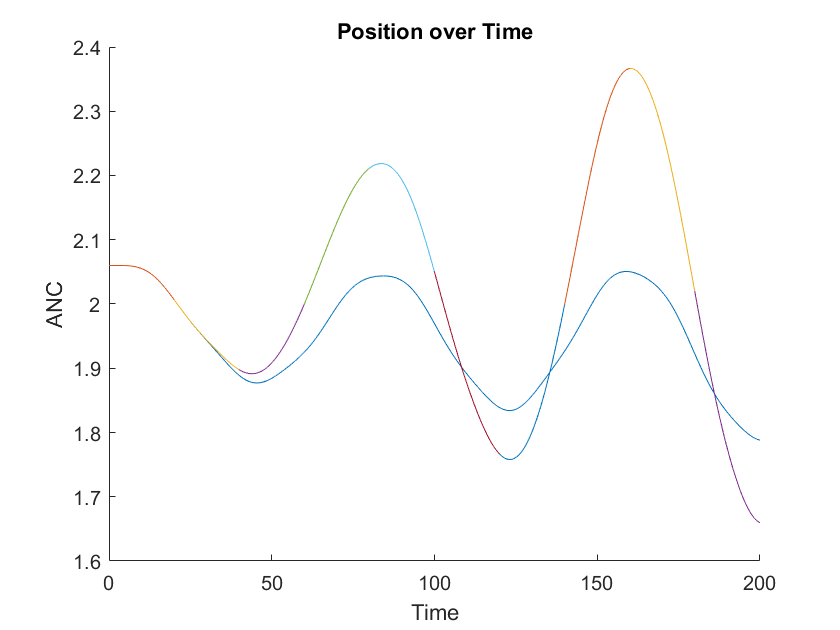

u_calc_full = zeros(size(u_nominal));
for k=1:N_cycles
    i = N_steps_per_cycle*(k-1);
    u_calc_full(i+1:i+N_steps_on_cycle,:) = u_calc(k)*(ones(N_steps_on_cycle,1));
end

figure()
% plot(time,y_neutrophils)
hold on
plot(time,rho(1:length(time)))
for k=1:N_cycles
    prev_i = N_cycledays*(k-1)/t_s;
    if k == 1
        prev_i = 1;
    end
    y_neutrophils = reshape(y_calc(1,1,prev_i:prev_i + N_steps_per_cycle),[1 N_steps_per_cycle+1]);
    plot(time(prev_i:prev_i + N_steps_per_cycle), y_neutrophils)
end
title('Position over Time')
xlabel('Time')
ylabel('ANC')
% legend('adaptive MPC','target')
hold off

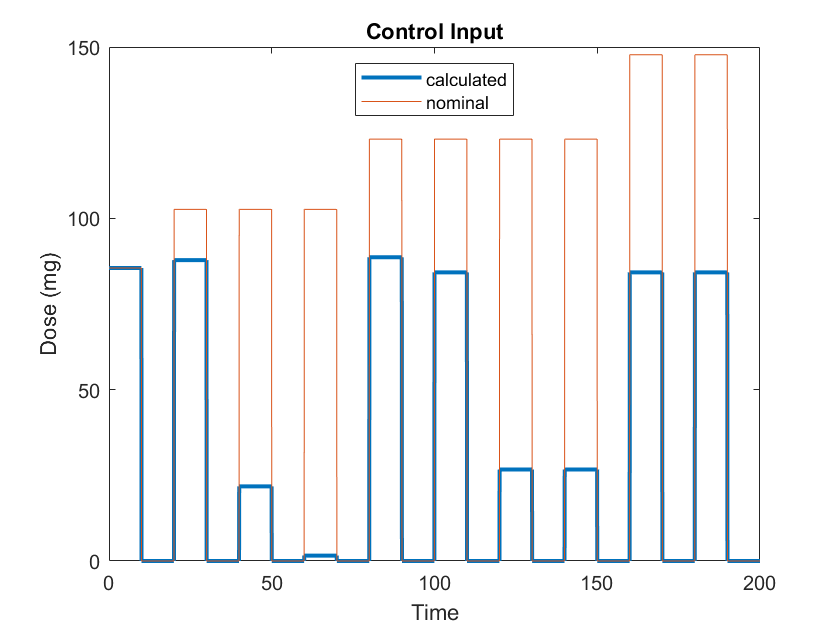


figure(6)
plot(time,u_calc_full, "LineWidth", 2)
hold on
plot(time,u_nominal)
title('Control Input')
xlabel('Time')
ylabel('Dose (mg)')
l = legend('calculated','nominal');
l.Location = "north";
hold off

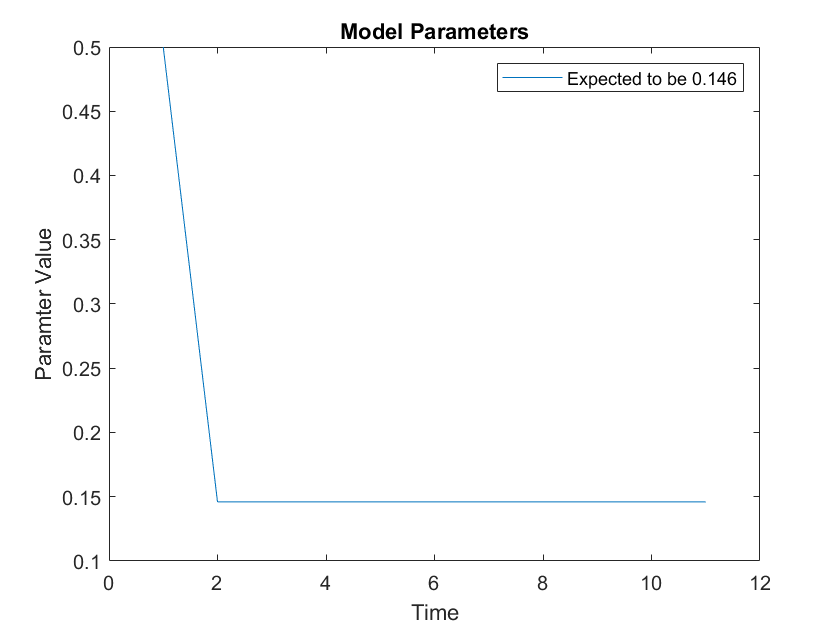


p1 = reshape(params_calc(1,1,:),[1 N_cycles+1]);
figure()
plot(p1)
title('Model Parameters')
xlabel('Time')
ylabel('Paramter Value')
legend('Expected to be 0.146')
hold off

## Let's try this again

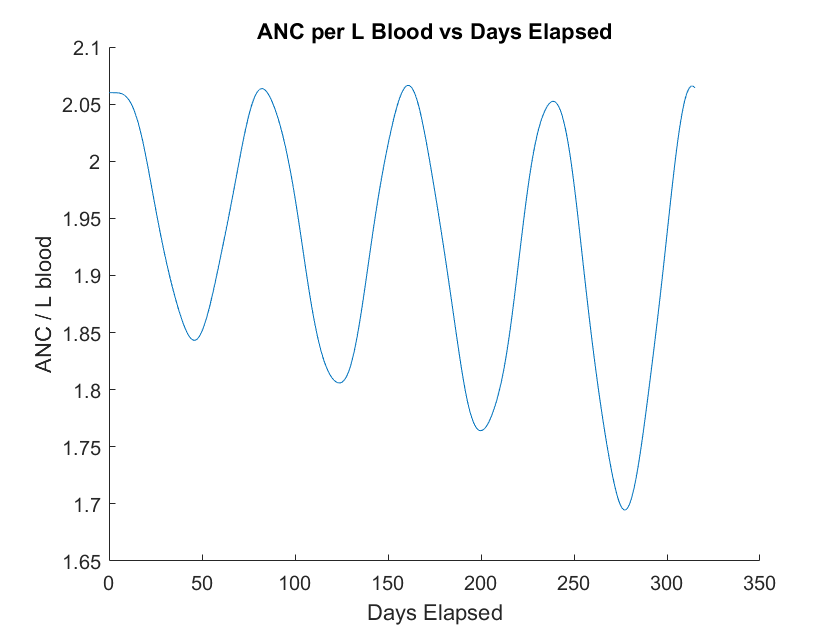

% Simulation Length
N_cyclestotal = 15;
N_cyclespred = 5;
N_days=N_cycledays*N_cyclestotal;
N_dayspred=N_cycledays*N_cyclespred;

t_s = step_size;
N_steps = N_days / t_s;
N_steps_per_day = 1 / t_s;
time = (0:t_s:N_days);

% Nominal trajectory with new time vector
x_nominal = zeros([N_steps+1 n]);
u_nominal = zeros([N_steps+1 1]);
rho = zeros([N_steps+1 m]);

u_k=50*bsa;
x_nominal(1,:) = x0;
rho(1,:) = g_nonlin(x0);

for k=1:N_days
    day_in_cycle = get_cycle_day(k, N_cycledays);
    for i=1:N_steps_per_day
        j = (N_steps_per_day*(k-1) + i);
        if day_in_cycle <= N_drugdays
            u_nominal(j,:) = u_k;
        end
        x_nominal(j+1,:) = jost_discrete(...
            (j+1)*t_s,x_nominal(j,:)',u_nominal(j,:),params,N_cycledays,N_drugdays,t_s ...
        );
        rho(j+1, :) = g_nonlin(x_nominal(j+1,:));
    end
    if day_in_cycle == N_cycledays
        x_k = x_nominal(j+1,:);
        if x_k(8) < lower
            u_k = 0.8*u_k;
        elseif x_k(8) > upper
            u_k = 1.2*u_k;
        end
    end
end
% rho = x_nominal(:,8);

figure()
hold on
xlabel('Days Elapsed')
ylabel('ANC / L blood')
title("ANC per L Blood vs Days Elapsed")
plot(time,rho)
hold off

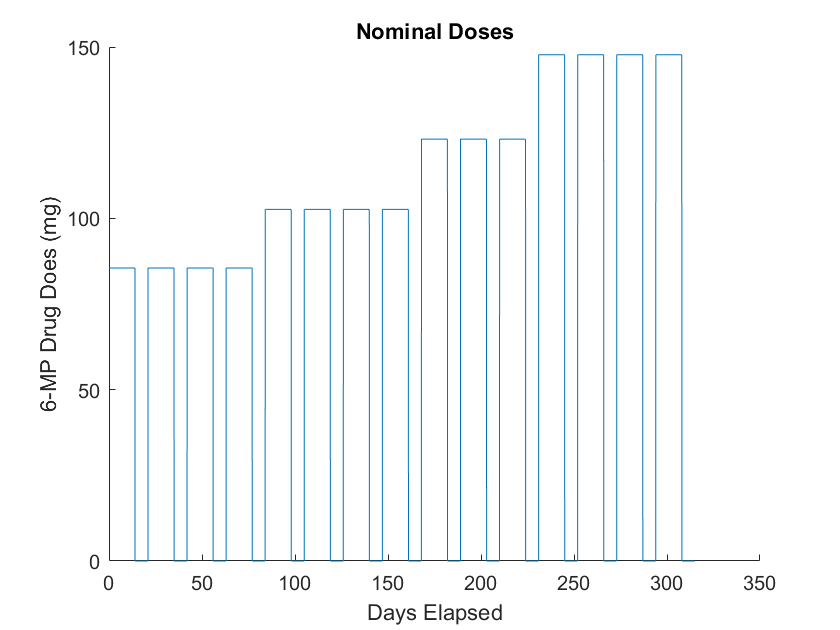


figure()
hold on
xlabel('Days Elapsed')
ylabel('6-MP Drug Does (mg)')
title("Nominal Doses")
plot(time,u_nominal)
hold off

## Simulate System

n_params = length(params);
x_calc = zeros([n,1,N_steps+1]);
y_calc = zeros([m,1,N_steps+1]);
params_calc = zeros([n_params,1,N_cyclestotal+1]);
u_calc = zeros([1,N_days]);

x_calc(:,:,1) = x0;
y_calc(:,:,1) = g_nonlin(x0);
params_calc(:,:,1) = params_guess;

for k=0:N_cycledays:N_days
    prev_step = N_steps_per_day*k + 1;  
    cycle = floor(k/N_cycledays)+1;
    
    f = @(p)calc_params(p, params, x0, u_calc, prev_step, N_cycledays, N_drugdays, t_s);
    [p_star, fval] = fmincon(f,params_calc(:,:,cycle));

%     if get_cycle_day(k, N_cycledays) <= N_drugdays
    g = @(u)calc_control(...
        p_star, rho, x_calc(:,:,prev_step), k, u, 10, 2.5, N_dayspred, N_cyclespred, N_cycledays, N_drugdays, t_s ...
    );

    init_guess_u = 50*bsa; %u_nominal(prev_step + 1);
    [u_star, gval] = fmincon(g,repmat(init_guess_u, [N_cyclespred 1]),[],[],[],[],repmat(0.01, [N_cyclespred 1]));
    u_calc(k+1:k+N_drugdays) = u_star(1);
    u_calc(k+N_drugdays+1:k+N_cycledays) = 0;
%     else
%         u_calc(k) = 0;
%     end
    params_calc(:,:,cycle+1) = p_star;
    
    for i=prev_step:prev_step + N_steps_per_day*N_cycledays - 1
        x_calc(:,:,i+1) = jost_discrete((i+1)*t_s,x_calc(:,:,i), u_star(1),params,N_cycledays,N_drugdays,t_s);
        y_calc(:,:,i+1) = g_nonlin(x_calc(:,:,i+1));
    end
end


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


## Plots

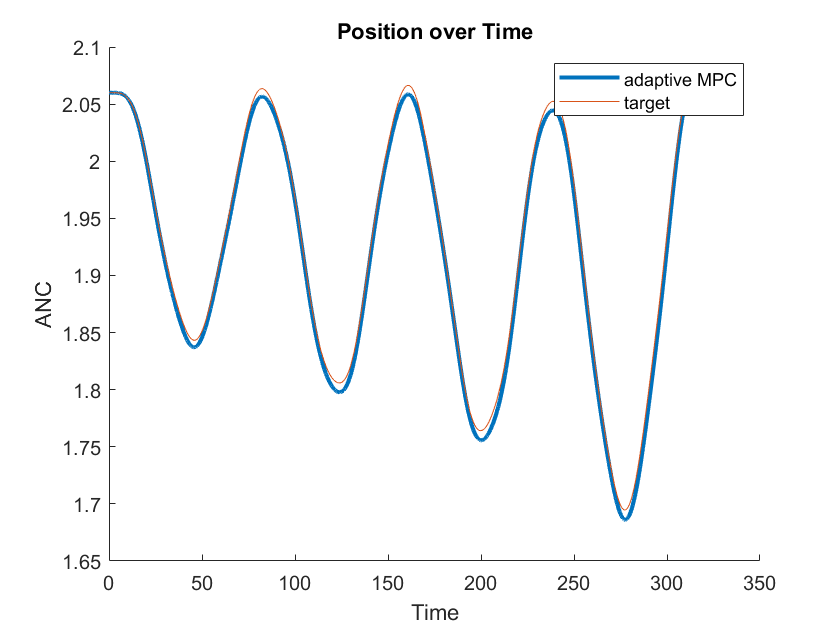

u_calc_full = zeros(size(u_nominal));
for k=1:N_days
    i = N_steps_per_day*(k-1);
    u_calc_full(i+1:i+N_steps_per_day,:) = u_calc(k)*(ones(N_steps_per_day,1));
end

y_neutrophils = reshape(y_calc(1,1,:),[1 length(y_calc)]);
figure()
% plot(time,y_neutrophils)
hold on
plot(time, y_neutrophils(1:N_steps+1), "LineWidth", 2)
plot(time,rho(1:length(time)))
title('Position over Time')
xlabel('Time')
ylabel('ANC')
legend('adaptive MPC','target')
hold off

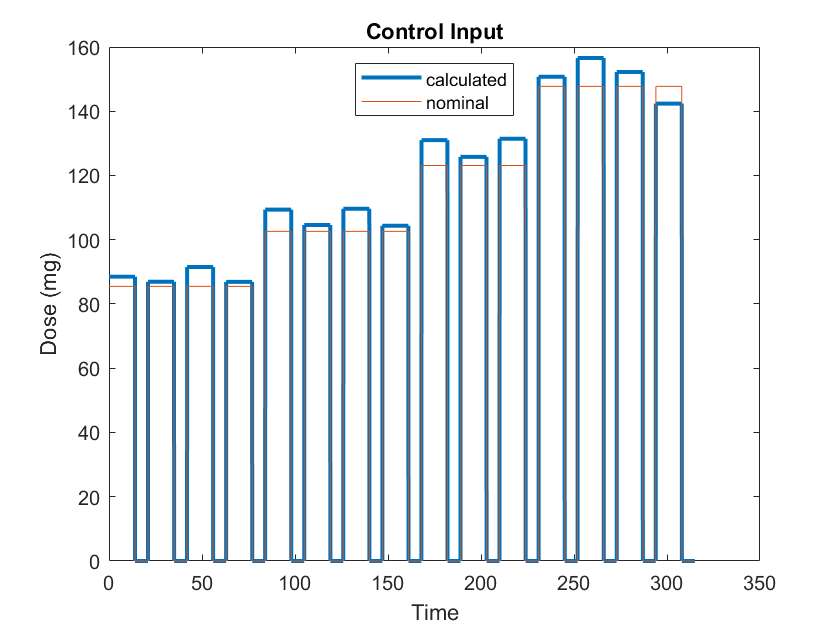


figure()
plot(time,u_calc_full, "LineWidth", 2)
hold on
plot(time,u_nominal)
title('Control Input')
xlabel('Time')
ylabel('Dose (mg)')
l = legend('calculated','nominal');
l.Location = "north";
hold off

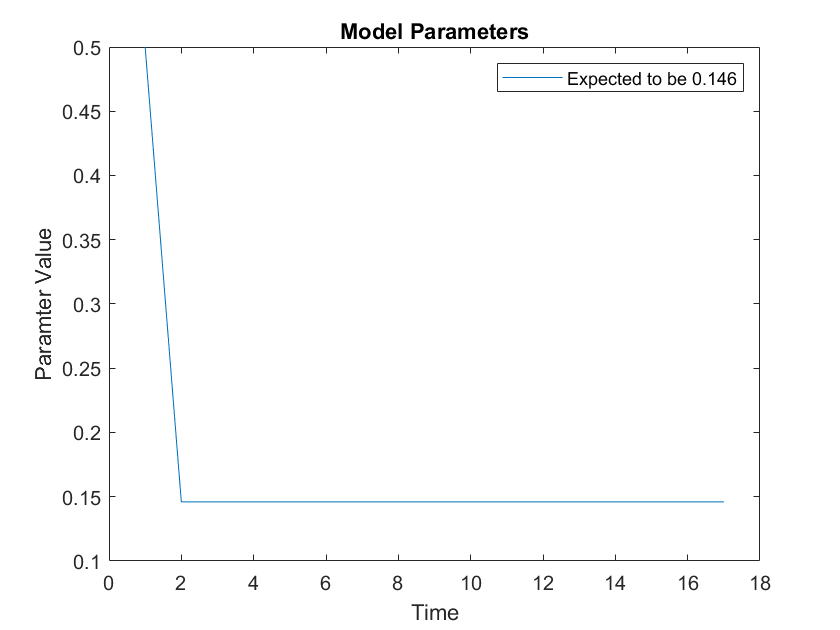


p1 = reshape(params_calc(1,1,:),[1 length(params_calc)]);
figure()
plot(p1)
title('Model Parameters')
xlabel('Time')
ylabel('Paramter Value')
legend('Expected to be 0.146')
hold off